# Project1 : Speech synthesis and perception

涂峻绫(12213010), 欧阳莹轩(12212961), 肖星辰(12212904), 欧阳安男(12211831)

## Introduction

## Results and Analysis

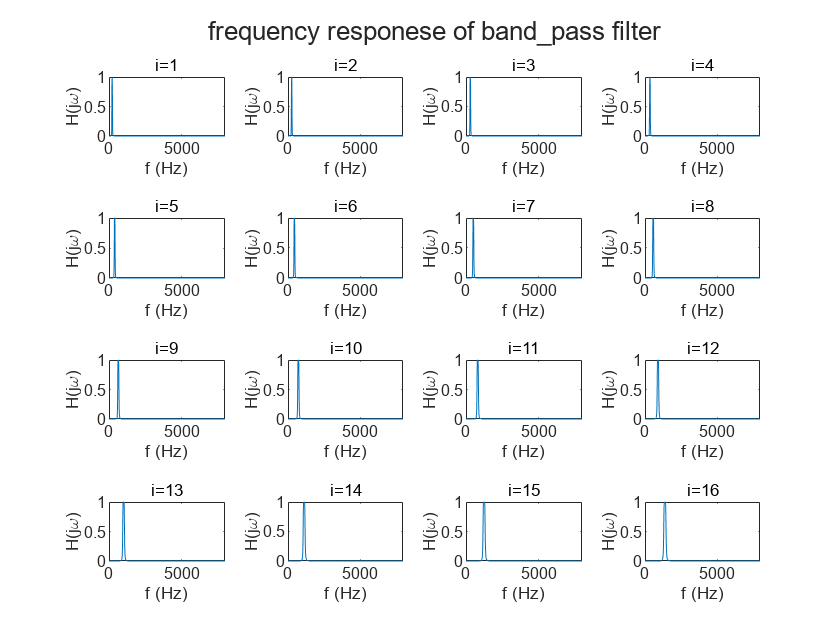

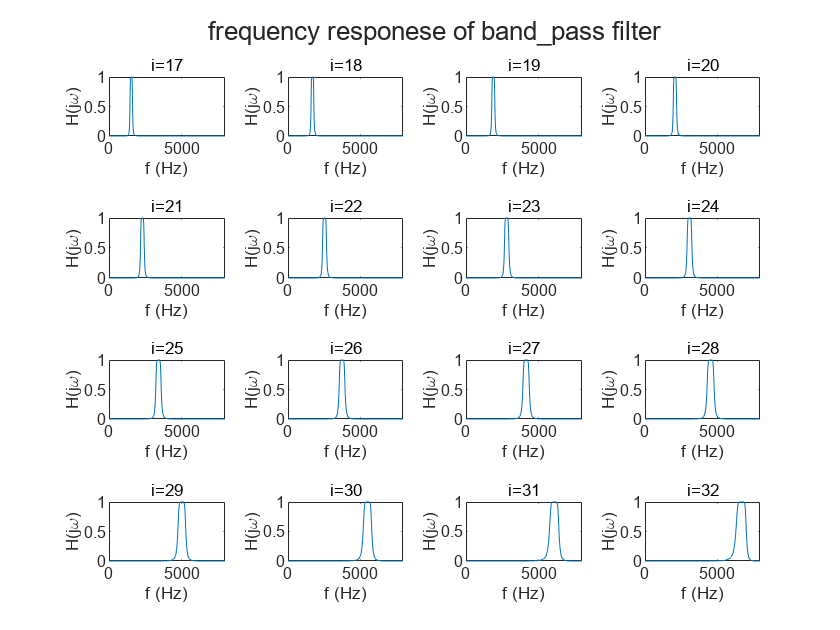

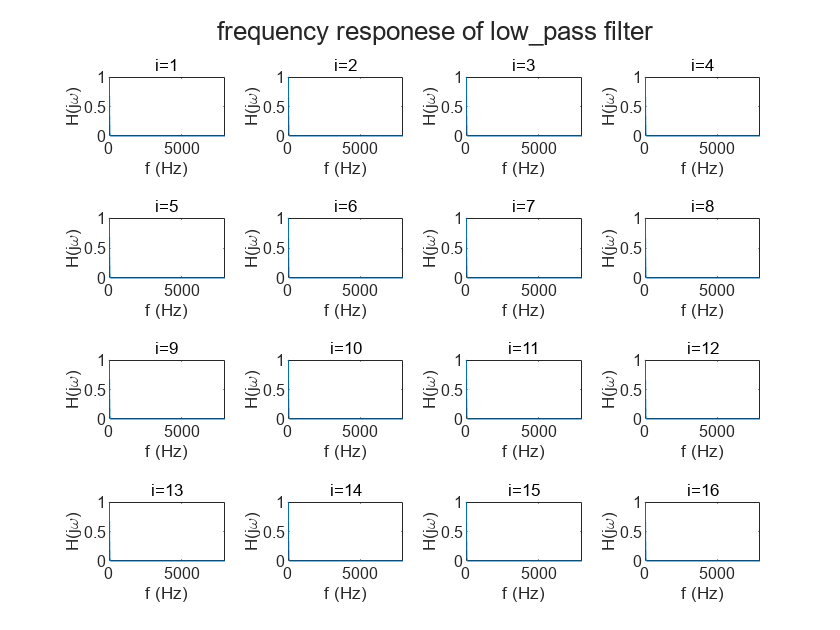

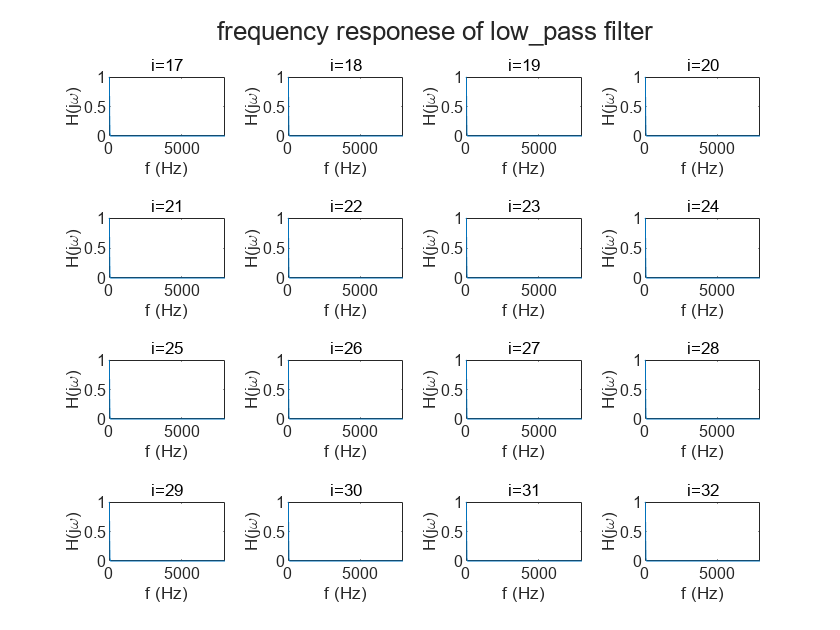

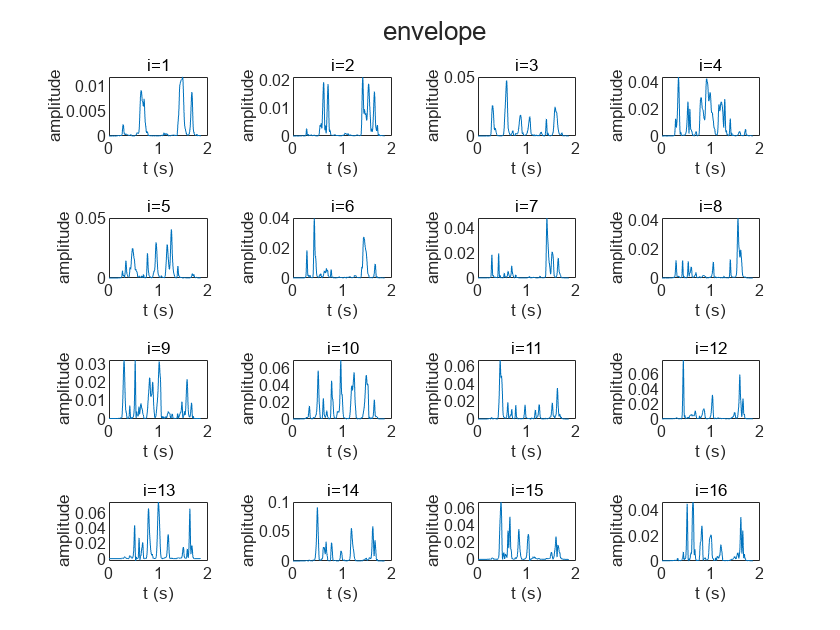

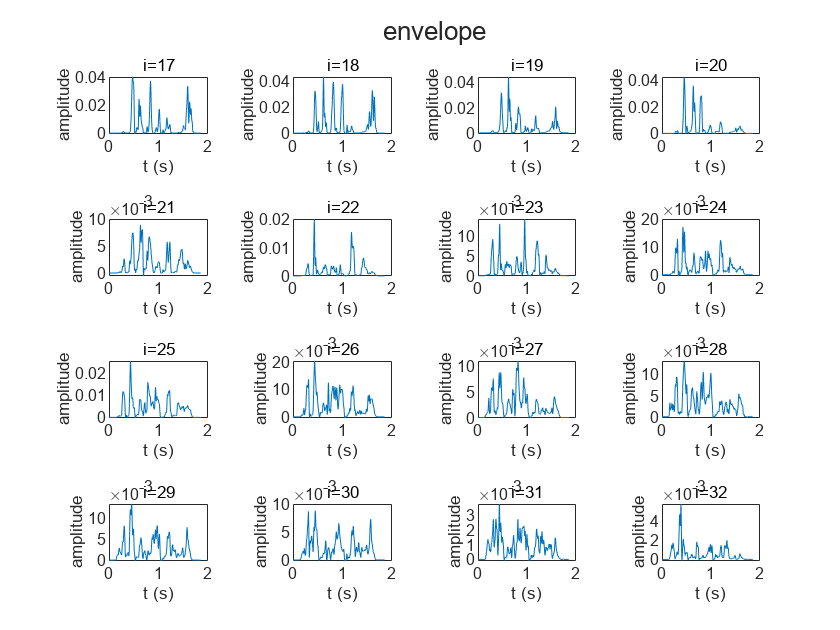

[s, fs] = audioread('proj1/C_01_02.wav');
res = speech_synthesis(s, fs, 32, 40);

audiowrite('3.wav', res, fs);

### Functions

The function to get the corresponding cochlea length (in $mm$) from a certain frequency (in $Hz$).

function d = freq2cochlea (f)
    d = log10(f./165.4 + 1) ./ 0.06;
end

The function to get the corresponding frequency (in $Hz$) from a certain cochlea length (in $mm$).

function f = cochlea2freq (d)
    f = 165.4 .* (10.^(0.06.*d) - 1);
end

The function to get the frequency (in $Hz$) equally divided by the cochlea length.

function f = divide_freq (n)
persistent d0 d1;
if isempty(d0)
    d0 = freq2cochlea(200);
    d1 = freq2cochlea(7000);
end
f = cochlea2freq(linspace(d0, d1, n + 1));
end

The function to get figure objects can contain given number of figure.

function figure_obj = get_figures(N, title, each_figure_num)
    if nargin < 3
        each_figure_num = 16;
        if nargin < 2
            title = '';
        end
    end

    figure_num = ceil(N/each_figure_num);
    figure_obj = gobjects(figure_num, 1);
    for i = 1:figure_num-1
        figure_obj(i) = figure();
        tiledlayout(4, 4);
        sgtitle(title);
    end
    last_figure_num = N - (figure_num-1) * each_figure_num;
    if last_figure_num == 0
        last_figure_num = each_figure_num;
    end
    last_figure_col = floor(sqrt(last_figure_num));
    last_figure_row = ceil(last_figure_num/last_figure_col);
    figure_obj(figure_num) = figure();
    tiledlayout(last_figure_row, last_figure_col);
    sgtitle(title);
end

The speech synthesis function.

function res = speech_synthesis(s, fs, N, cut_off, band_order, low_order)
if nargin < 5
    band_order = 4;
    low_order = 6;
end
% prepare the figure
band_figure = get_figures(N, 'frequency responese of band\_pass filter');
low_figure = get_figures(N, 'frequency responese of low\_pass filter');
envelope_figure = get_figures(N, 'envelope');
% initialize res and t
res = zeros(length(s), 1);
t = (0:length(s)-1)'./fs;
% get the band edge's frequency
f = divide_freq(N);
% for each band
for i = 2:length(f)
    lower = f(i-1);
    higher = f(i);
    % design band-pass filter
    [b,a] = butter(band_order, [lower higher]/(fs/2));
    % calculate and plot the frequency response of the band-pass filter
    [H, omega] = freqz(b,a);
    figure(band_figure(ceil((i-1)/16)));
    nexttile;
    plot(omega * (fs/(2*pi)),abs(H));
    xlabel('f (Hz)');
    ylabel('H(j\omega)');
    title(['i=' num2str(i-1)])
    % do band-pass filtering
    y = filter(b, a, s);
    % do full-wave rectification
    y = abs(y);
    % design low-pass filtering
    [b,a] = butter(low_order, cut_off/(fs/2));
    % calculate and plot the frequency response of the low-pass filter
    [H, omega] = freqz(b,a);
    figure(low_figure(ceil((i-1)/16)));
    nexttile;
    plot(omega * (fs/(2*pi)),abs(H));
    xlabel('f (Hz)');
    ylabel('H(j\omega)');
    title(['i=' num2str(i-1)])
    % do low-pass filtering
    y = filter(b, a, y);
    % calculate and plot the envelope
    figure(envelope_figure(ceil((i-1)/16)));
    nexttile;
    plot(t,y);
    xlabel('t (s)');
    ylabel('amplitude');
    title(['i=' num2str(i-1)])
    % generate sinewave
    sinwave = sin((2*pi*(lower+higher)/2) .* t);
    % multiple the sinwave
    y = sinwave .* y;
    % add to the result
    res = res + y;
end
% do energy normalization
res = res .* (norm(s)/norm(res));
end

## Expeience

........................